# Example 5.2: Estimation with Incorrect Postulated Model

Note: this script reproduces Example 5.2 (Section 5.1.1) of **Statistics for Chemical Engineers**: fitting a linear model to data that do not follow it. Victor Z UW-Madison, 2020 illustrate simple linear estimation with wrong model

clc; clear all; close all hidden; 

## Data

generate data for input

rng(0)
S=100;
xobs=rand(S,1);

% generate true output
theta=2;
y=theta*xobs.^2;

% add noise
sigma=0.25;
eps=normrnd(0,sigma,S,1);
yobs=y+eps;

## Estimate

now get estimate htheta that extracts max knowledge from data

htheta=(xobs'*yobs)/(xobs'*xobs)

htheta =           1.51


% plot model prediction
ypred=htheta*xobs;

figure(1)
subplot(2,2,1)
plot(xobs,ypred,'black-','LineWidth',1.5)
hold on
plot(xobs,yobs,'blacko','MarkerFaceColor','w')
hold on
grid on
legend('Model','Data','location','southeast')
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$y$','Interpreter','latex','FontSize',14)

% parity plot
subplot(2,2,2)
yy=linspace(min(yobs),max(yobs))

yy =          -0.39         -0.36         -0.34         -0.31         -0.28         -0.25         -0.23         -0.20         -0.17         -0.15         -0.12         -0.09         -0.07         -0.04         -0.01          0.02          0.04          0.07          0.10          0.12          0.15          0.18          0.21          0.23          0.26          0.29          0.31          0.34          0.37          0.40          0.42          0.45          0.48          0.50          0.53          0.56          0.58          0.61          0.64          0.67          0.69          0.72          0.75          0.77          0.80          0.83          0.86          0.88          0.91          0.94


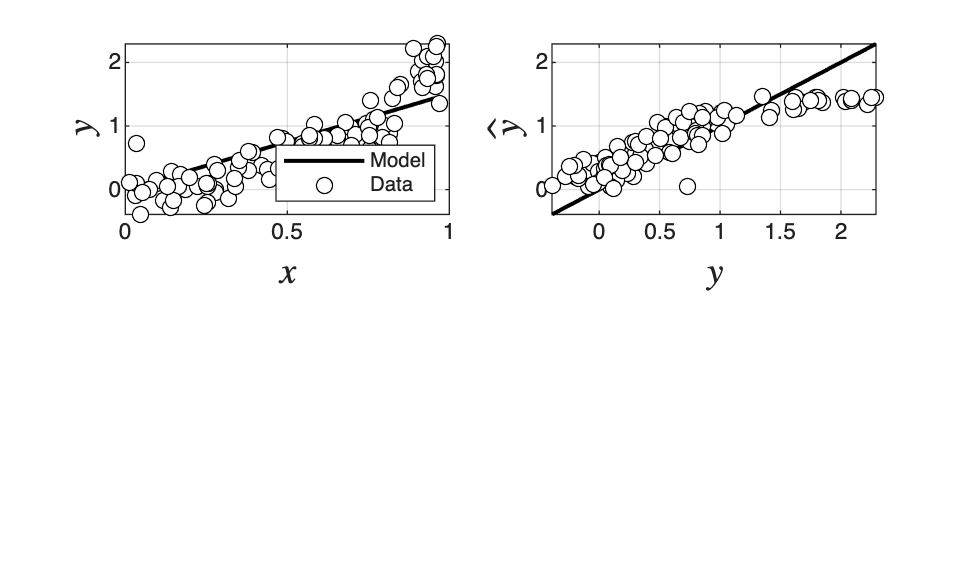

plot(yy,yy,'black-','LineWidth',1.5)
hold on
plot(yobs,ypred,'blacko','MarkerFaceColor','w')
axis([min(yobs) max(yobs) min(yobs) max(yobs)])
grid on
hold on
xlabel('$y$','Interpreter','latex','FontSize',14)
ylabel('$\hat{y}$','Interpreter','latex','FontSize',14)

## Residuals

plot residuals

epsm=yobs-ypred

epsm =          -0.35
          0.49
         -0.38
          0.32
         -0.29
         -0.05
         -0.41
         -0.10
          0.58
          0.84
         -0.24
         -0.11
          0.18
          0.08
         -0.19


xx=linspace(0,S)

xx =              0          1.01          2.02          3.03          4.04          5.05          6.06          7.07          8.08          9.09         10.10         11.11         12.12         13.13         14.14         15.15         16.16         17.17         18.18         19.19         20.20         21.21         22.22         23.23         24.24         25.25         26.26         27.27         28.28         29.29         30.30         31.31         32.32         33.33         34.34         35.35         36.36         37.37         38.38         39.39         40.40         41.41         42.42         43.43         44.44         45.45         46.46         47.47         48.48         49.49


yy=linspace(0,0)

yy =              0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0


subplot(2,2,3)
plot(xx,yy,'black-','LineWidth',1.5)
hold on
plot(epsm,'blacko','MarkerFaceColor','w')
axis([0,S,-3*sigma,+3*sigma])
hold on
grid on
xlabel('$\omega$','Interpreter','latex','FontSize',14)
ylabel('$\epsilon_\omega$','Interpreter','latex','FontSize',14)

pd = fitdist(epsm,'Normal')

pd =   NormalDistribution

  Normal distribution
       mu = -0.0868576   [-0.155777, -0.0179379]
    sigma =   0.347339   [0.304966, 0.403496]



subplot(2,2,4)
histogram(epsm,'BinWidth',0.1,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
xx=linspace(-1,1)

xx =          -1.00         -0.98         -0.96         -0.94         -0.92         -0.90         -0.88         -0.86         -0.84         -0.82         -0.80         -0.78         -0.76         -0.74         -0.72         -0.70         -0.68         -0.66         -0.64         -0.62         -0.60         -0.58         -0.56         -0.54         -0.52         -0.49         -0.47         -0.45         -0.43         -0.41         -0.39         -0.37         -0.35         -0.33         -0.31         -0.29         -0.27         -0.25         -0.23         -0.21         -0.19         -0.17         -0.15         -0.13         -0.11         -0.09         -0.07         -0.05         -0.03         -0.01


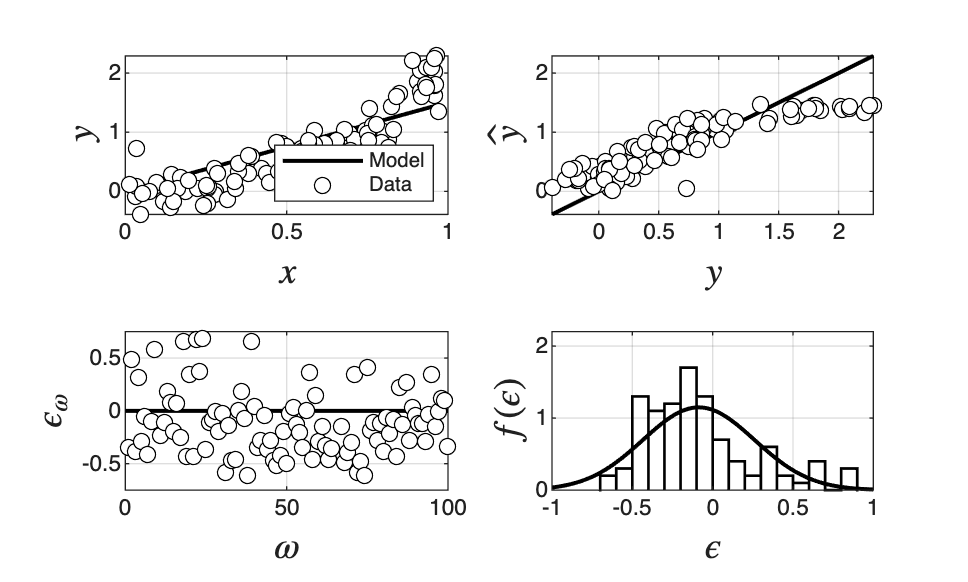

plot(xx,normpdf(xx,pd.mu,pd.sigma),'black-','LineWidth',1.5)
axis([-1 1 0 2.2])
grid on
xlabel('$\epsilon$','Interpreter','latex','FontSize',14)
ylabel('$f(\epsilon)$','Interpreter','latex','FontSize',14)
print -depsc ch5_results_lin_est_wrong.eps

## Note

As in the book, the residuals show a trend and are not Gaussian: residual analysis reveals that the postulated model is not appropriate.